# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;

## Generate a random physical topology

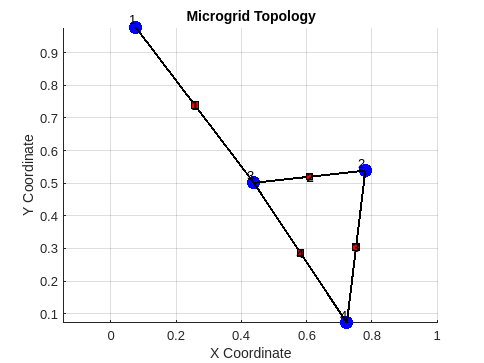

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
    -1    -1     0     1
     0    -1    -1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



coords =     0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721


adjMatrix =      0     0     1     0
     0     0     1     1
    -1    -1     0     1
     0    -1    -1     0


B_il =      1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     0.5593    1.7645   -0.2359
    1.7645   10.4558   -0.7659
   -0.2359   -0.7659    0.4001


KVal =   -24.1105    1.5258   -0.2350


LVal =  -106.8326   15.7223  -33.4809


nuVal = -3.3976

rhoVal = 0.2944

status = logical
   1


PVal =     0.5600    1.7680   -0.2366
    1.7680   10.4478   -0.7655
   -0.2366   -0.7655    0.4001


KVal =   -19.7110    1.6786   -0.2418


LVal =   -88.0431   13.0268  -27.7440


nuVal = -3.3869

rhoVal = 0.2953

status = logical
   1


PVal =     0.5430    1.7521   -0.2305
    1.7521   10.6142   -0.7677
   -0.2305   -0.7677    0.4001


KVal =   -21.6588    1.5215   -0.2299


LVal =   -98.6422   14.2535  -30.0466


nuVal = -3.4783

rhoVal = 0.2876

status = logical
   1


PVal =     0.5521    1.7643   -0.2341
    1.7643   10.5314   -0.7663
   -0.2341   -0.7663    0.4001


KVal =   -37.6724    1.4161   -0.2302


LVal =  -169.3832   24.7012  -52.3596


nuVal = -3.4235

rhoVal = 0.2922

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0057

nuBarVal = -3.5462e-12

rhoBarVal = 0.0291

status = logical
   1


PBarVal = 0.0088

nuBarVal = -8.5351e-10

rhoBarVal = 0.0252

status = logical
   1


PBarVal = 0.0073

nuBarVal = -1.2000e-10

rhoBarVal = 0.0267

status = logical
   1


PBarVal = 0.0075

nuBarVal = -1.6328e-10

rhoBarVal = 0.0220

status = logical
   1


Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 

## Centralized Local Controller Design

BarGamma = 5;    % Fixed value for gammaBar

MOSEK Version 10.2.1 (Build date: 2024-6-13 06:50:33)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 60              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 24              
  Matrix variables       : 12 (scalarized: 216)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - prima

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1


[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma) % topologyMetrics may be the B matrix 
% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

DG{1}

ans = struct with fields:
              R: 0.0227
              L: 0.0150
              C: 0.0029
              Y: 3.2464
              A: [3×3 double]
              B: [3×1 double]
             P0: [3×3 double]
             K0: [-93.6008 13.4547 -55.5306]
             nu: -56.2435
            rho: 4.2486
    gammaTilde0: 14.0609


DG{numOfDGs}

ans = struct with fields:
              R: 0.0260
              L: 0.0195
              C: 0.0024
              Y: 3.2735
              A: [3×3 double]
              B: [3×1 double]
             P0: [3×3 double]
             K0: [-151.9952 21.6891 -89.1955]
             nu: -57.2981
            rho: 4.2417
    gammaTilde0: 14.3245



Line{1}

ans = struct with fields:
      R: 0.0291
      L: 0.0113
      A: -2.5672
      B: 88.2481
     P0: 0.1010
     nu: -17.4824
    rho: -16.9640


Line{numOfLines}

ans = struct with fields:
      R: 0.0220
      L: 0.0149
      A: -1.4790
      B: 67.0796
     P0: 0.1120
     nu: -16.3833
    rho: -16.0519


## Global Controller Design

isSoft = 1; % Set to 1 to avoid the hard graph constraint

[DG,Line,statusGlobalController] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

Unrecognized field name "rhoBar".

Error in globalControlDesign (line 132)
    rhoBar_l = Line{l}.rhoBar;